# ARTIFICIAL INTELLIGENCE (A.I.) AND MACHINE LEARNING (M.L.)

**What is Artificial Intelligence**: Artificial intelligence (AI) refers to computer systems capable of performing complex tasks that historically only a human could do, such as reasoning, making decisions, or solving problems.

**What is Machine Learning**: Machine learning is a branch of artificial intelligence (AI) and computer science which focuses on the use of data and algorithms to imitate the way that humans learn, gradually improving its accuracy.

**What is Deep Learning: **Deep learning is a branch of machine learning that is made up of a neural network with three or more layers.

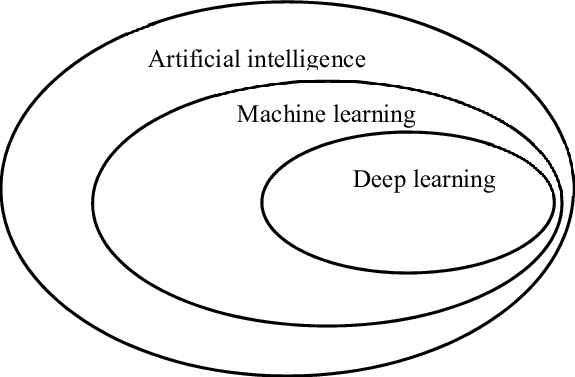

## Types of Machine Learning:

- Supervised Learning, which consist of regression and classification problems

- Semi-supervised: Generative AI, such as GTP4.5 Dall-E-3, Stable Diffusion e.t.c.

- Unsupervised Learning:10

- Reinforcement Learning: Where the model/agent learns to perfom actions, AlphaGO, AlphaZero(chess), AlphaPhold(protein structure discovery), GPT tuning e.t.c.

## **Regression**

**In this class we will mainly focus on regression models. **

*Regression* problems pop up whenever we want to predict a numerical value. Common examples include predicting prices (of homes, stocks, etc.), predicting the length of stay (for patients in the hospital), forecasting demand (for retail sales), engine power output given some initial inputs, among numerous others.

## Linear Regression

*Linear regression* is both the simplest and most popular among the standard tools for tackling regression problems. Dating back to the dawn of the 19th century ([Gauss, 1809](https://d2l.ai/chapter_references/zreferences.html#id80), [Legendre, 1805](https://d2l.ai/chapter_references/zreferences.html#id164)), linear regression flows from a few simple assumptions. First, we assume that the relationship between features $x$ and target $y$ is approximately linear, i.e., that the conditional mean $E\left[ Y | X=x \right]$ can be expressed as a weighted sum of the features $x$. This setup allows that the target value may still deviate from its expected value on account of observation noise. Next, we can impose the assumption that any such noise is well behaved, following a Gaussian distribution. Typically, we will use $n$ to denote the number of examples in our dataset. We use superscripts to enumerate samples and targets, and subscripts to index coordinates. More concretely, $x^{(i)}$ denotes the $i^{th}$ sample and  $x_{j}^{(i)}$ denotes its $j^{th}$th coordinate.

## Model

At the heart of every solution is a model that describes how features can be transformed into an estimate of the target. The assumption of linearity means that the expected value of the target ($y$) can be expressed as a weighted sum of the features ($x_{j}$):

## 
$$y^{(i)} = {w_{j}*x_{j}}^{(i)}$$


## But how do we find the best $w_{j}$ for each input feature $j$?

Let's see in the case that we have 2 data points and we assume that there is no bias/intercept/offset.

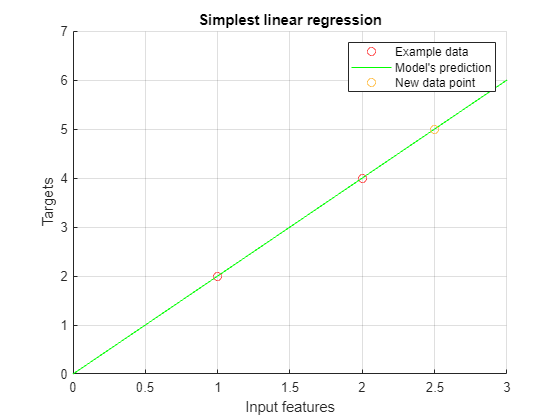

% The simplest case is when we have two, 2-d -> j = 1, data points.
x = [1, 2];
y = [2, 4];

figure
title("Simplest linear regression")
hold on
grid on
plot(x, y, 'or', DisplayName="Example data")

w = (y(2) - y(1)) / (x(2) - x(1));
x_space = 0:3;
y_pred = w * x_space;
plot(x_space, y_pred, "g", DisplayName="Model's prediction")
xlabel("Input features")
ylabel("Targets")
xlim([0, 3])
ylim([0, 7])
legend()

% How would we evaluate a new input data point?
x_new = 2.5;
y_pred_new = w * x_new;
plot(x_new, y_pred_new, 'o', DisplayName="New data point",Color="#FFA500")

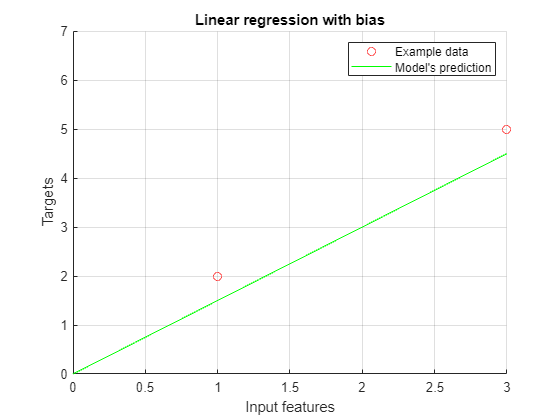

% Let's see what happens if our data follow a linear trend but there is an
% offset.
x = [1, 3];
y = [2, 5];
figure
title("Linear regression with bias")
hold on
grid on

plot(x, y, 'or', DisplayName="Example data")

w = (y(2) - y(1)) / (x(2) - x(1));
x_space = 0:3;
y_pred = w * x_space;
plot(x_space, y_pred, "g", DisplayName="Model's prediction")
xlabel("Input features")
ylabel("Targets")
xlim([0, 3])
ylim([0, 7])
legend()

We see that our line is off by an **offset**. This offset is usually called **intercept** in the linear regression and **bias** in the more general cases. We will refer to it as bias from now on.

In order to find the bias we must chagne our model from 

$\hat{y}_i = w * x_i$ to  $\hat{y_i} = w * x_i + b$  or in vector form $\hat{y}_i = \left[ w \; b \right] *\left[ x_i  \; 1 \right ] ^T$

In the case of 2 data point we can find the optimal w and b by solving the 2x2 system of equations.

However, it is important to be able to find a general solution that is free of the number of data points. The most popular method is the least square. 

In order to find the best w and b values we must describe a function to optimized them based on. This function is usually called the loss function and is denoted by ***L*****.** Usually the simplest loss function is the $\textbf{L} = \sum_{i=1}^N \left(y_i - \hat{y}_i  \right)^2$ instead of the simple $\textbf{L} = \sum_{i=1}^N \left(y_i - \hat{y}_i  \right)
$, since we prefer to penelize higher errors.

In order to find the best w and w values we just take the derivates with respect to **L**, set them to zero and solve the resulting equation.

Solving for **w** we get:


$$\frac{\partial L} {\partial w} = 0 
\Rightarrow
\frac{\partial\sum_{i=1}^N \left(y_i - \hat{y}_i  \right)^2}{\partial w} = 0
\Rightarrow

 \frac{\sum_{i=1}^N \partial\left(y_i - w * x_i - b \right)^2}{\partial w} = 0 
\Rightarrow
\\
\Rightarrow
\sum_{i=1}^N \left(y_i - w * x_i - b \right) * (-x_i) = 0
\Rightarrow
\\
\Rightarrow
\sum_{i=1}^N y_i * x_i - w* \sum_{i=1}^N x_i^2  - b* \sum_{i=1}^N x_i = 0\;\; (1)$$


Solving for **b** we get:


$$\frac{\partial L} {\partial b} = 0 
\Rightarrow
\frac{\partial\sum_{i=1}^N \left(y_i - \hat{y}_i  \right)^2}{\partial b} = 0
\Rightarrow

 \frac{\sum_{i=1}^N \partial\left(y_i - w * x_i - b \right)^2}{\partial b} = 0 
\Rightarrow
\\
\Rightarrow
\sum_{i=1}^N \left(y_i - w * x_i - b \right)  *(-1) = 0
 \Rightarrow
\\
 \Rightarrow
N* b= \sum_{i=1}^N y_i - w* \sum_{i=1}^N x_i  
 \Rightarrow
\\
 \Rightarrow
b= \bar{y} - w* \bar{x}
\;\; (2)
$$


If we substitue **b** from **(2)** to **(1)** we get


$$(1),\; (2)
\Rightarrow 
\sum_{i=1}^N y_i * x_i - w* \sum_{i=1}^N x_i^2  -  \frac{\left( \sum_{i=1}^N y_i - w* \sum_{i=1}^N x_i \right)}{N}  * \sum_{i=1}^N x_i =0
\Rightarrow 
\\
\Rightarrow
\sum_{i=1}^N y_i * x_i - w*  \sum_{i=1}^N x_i^2  -  \frac{\sum_{i=1}^N y_i \sum_{i=1}^Nx_i}{{N}} + w*\frac{\left( \sum_{i=1}^N x_i^\right)^2}{N}=0
\Rightarrow 
\\
\Rightarrow

w* \sum_{i=1}^N x_i^2  - w*\frac{\left( \sum_{i=1}^N x_i^\right)^2}{N}   = \sum_{i=1}^N y_i *x_i  -  \frac{\sum_{i=1}^N y_i \sum_{i=1}^Nx_i}{N}

\Rightarrow 
\\
\Rightarrow
w = 
\frac{ 
           \sum_{i=1}^N y_i *x_i  -  \frac{ 
                                                          \sum_{i=1}^N y_i \sum_{i=1}^Nx_i
                                                          } 
                                                           {N} 
       }
       { 
        \sum_{i=1}^N x_i^2  - \frac{\left( \sum_{i=1}^N x_i \right) ^2}{N} 
      }
    \Rightarrow 
\\
\Rightarrow
w =  \frac{Cov\left[x,y\right]}{Var\left[x\right]}$$


Let's create a function that takes two matrices, X and Y and return us the w and b paremeters

[w, b] = ordinary_least_squares(x, y)

w = 1.5000

b = 0.5000

ans = 1

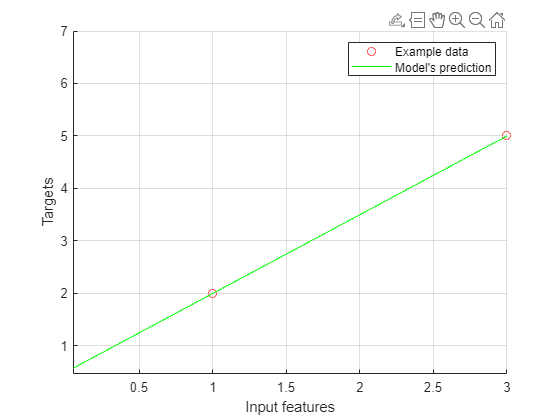

% Print the new prediction
figure
hold on
grid on
x_space = 0:3;
y_pred = w * x_space + b;
plot(x, y, 'or', DisplayName="Example data")
plot(x_space, y_pred, "g", DisplayName="Model's prediction")
xlabel("Input features")
ylabel("Targets")
xlim([0, 3])
ylim([0, 7])
legend()

load carsmall
whos

  Name                Size            Bytes  Class     Attributes

  Acceleration      100x1               800  double              
  Cylinders         100x1               800  double              
  Displacement      100x1               800  double              
  Horsepower        100x1               800  double              
  MPG               100x1               800  double              
  Mfg               100x13             2600  char                
  Model             100x33             6600  char                
  Model_Year        100x1               800  double              
  Origin            100x7              1400  char                
  Weight            100x1               800  double              
  ans                 1x1                 8  double              
  b                   1x1                 8  double              
  t                   1x94              752  double              
  w                   1x1                 8  double              
  x      

isdata = isfinite(MPG)&isfinite(Weight)&isfinite(Horsepower);
y = MPG(isdata);
x = Weight(isdata);
N = length(y)

N = 93

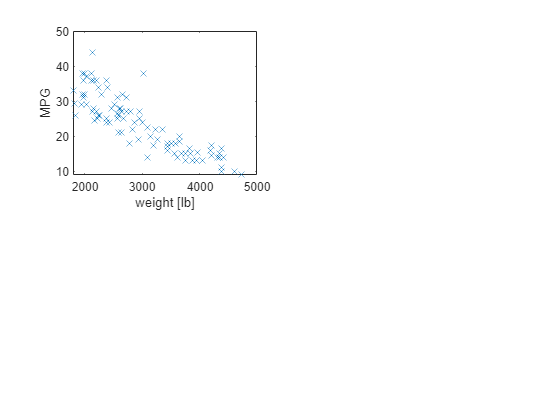

clf
subplot(2,2,1)
plot(x,y,'x')
xlabel('weight [lb]')
ylabel('MPG')
hold on

rng("default")
x = sort(rand(30, 1));
y = true_fuction(x) + rand(30, 1) * 0.3;

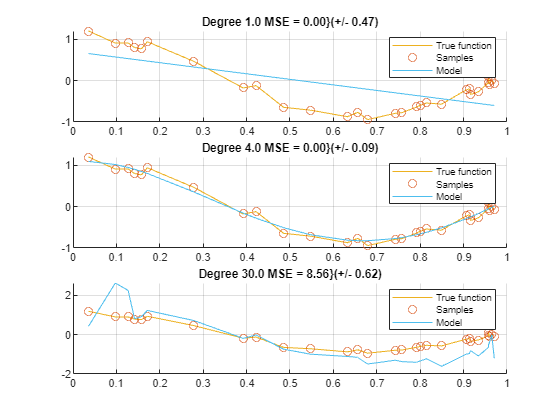

warning('off')

N = [1, 4, 30];
tiledlayout(4,5);
for case_id=1:3
    n = N(case_id);
    polynomial_coefs = polyfit(x, y, n);
    y_hat = polyval(polynomial_coefs, x);
    [error, error_std]  = rmse(y, y_hat);
    subplot(3, 1, case_id)
    hold on
    p = plot(x, y, DisplayName="True function");
    p.Color = "#EDB120";
    p = scatter(x, y, DisplayName="Samples ");
    p.ColorVariable = "#0072BD";
    p = plot(x, y_hat, DisplayName="Model");
    p.Color = 	"#4DBEEE";
    grid on
    legend()
    title_text = sprintf("Degree %0.1f MSE = %0.2f}(+/- %0.2f)", n, error, error_std );
    title(title_text);
end

function [w, b] = ordinary_least_squares(X, Y)
    N = size(X, 2);
    x_squared_sum = sum(X.^2);
    x_y_sum = sum(X .* Y);
    x_sum = sum(X);

    y_sum = sum(Y);
    x_sum_squared = x_sum ^ 2/ N;

    w = (x_y_sum - (x_sum*y_sum)/N) / (x_squared_sum - x_sum_squared);
    b = y_sum / N - w * x_sum/N;

end

function [y] = true_fuction(x)

    y = cos(1.5 * pi *x);
end

function [error, error_std] = rmse(y, y_hat)
    error = round(sqrt(sum(y -y_hat).^2), 3);
    error_std = round(std(y - y_hat), 3);
end

add polynomial features/logistic regression

**QUESTION**

- What happens, in the above examples, if there is noise to our data?

- How reliable are the linear models in these cases?

- What can we do to solve this problem?